rosinit;

Launching ROS Core...
Done in 0.39123 seconds.
Initializing ROS master on http://192.168.0.164:11311.
Initializing global node /matlab_global_node_63361 with NodeURI http://ubuntuStation.Home:35215/ and MasterURI http://localhost:11311.


node = ros2node('/shelfino1/global_costmap/global_costmap');

subscriber = ros2subscriber(node, '/shelfino1/global_costmap/costmap');

msg = receive(subscriber)

msg = struct with fields:
    MessageType: 'nav_msgs/OccupancyGrid'
         header: [1×1 struct]
           info: [1×1 struct]
           data: [23000000×1 int8]


occupancyGrid = reshape(msg.data, msg.info.width, msg.info.height);

map = binaryOccupancyMap(occupancyGrid);

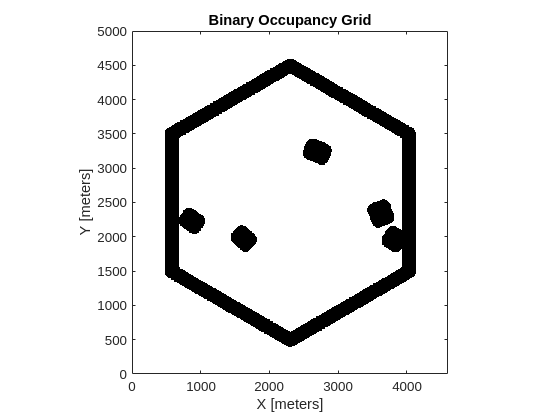

figure
show(map);

hold on

x0 = 1

x0 = 1

y0 = 1

y0 = 1

x1 = msg.info.width

x1 = uint32
5000

y1 = msg.info.height

y1 = uint32
4600

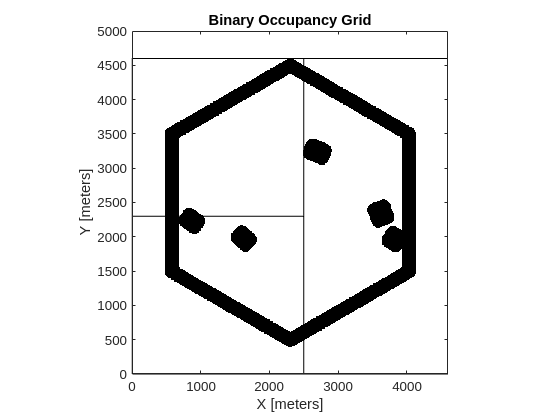


rectangle('Position', [x0 y0 x1/2 y1]);
rectangle('Position', [x1/2 y0 x1 y1]);
hold off;

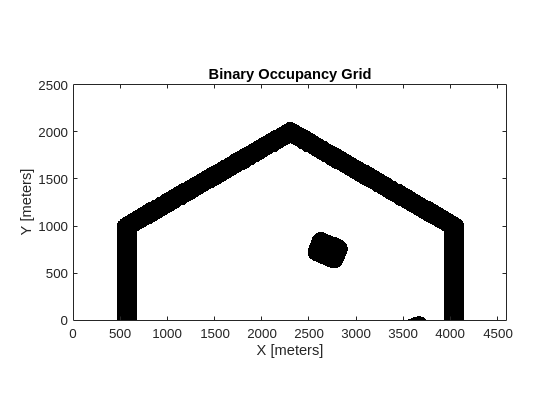


sub_1 = occupancyGrid(x0:x1/2, y0:y1);
sub_1_map = binaryOccupancyMap(sub_1);
show(sub_1_map);

rosshutdown;